## **Prueba del método numérico del marco**

Autor: Víctor García Carrera, victor.garciacarrera@estudiante.uam.es

% Limpiamos variables y el espacio de trabajo
clear all clc clf

%%%% INICIALIZACIÓN
%%
%
%            n: dimensión del espacio de Hilbert H (ejemplo n=2, R2)
%            Nt: número de iteraciones temporales
%            k: número de vectores del marco
%            marco: Lista con los k vectores (de dim n) que forman el
%            marco
%            A: Limite inferior del marco
%            B: Limite superior del marco
%            x: vector (de dim n) a aproximar.

n = 2;  % Ejemplo en R2
Nt = [1,5,10,20,80]; % Lista de num de iteraciones para cada aproximación
num_aprox = length(Nt);  % Numero de pruebas a realizar del método
k = 3;  % Ejemplo Marco con 3 vectores

%% MARCO GENERAL
x1 = sqrt(2/3)*[1,1];   %PARSEVAL con [1,0]
x2 = sqrt(2/3)*[-1/2,sqrt(3)/2];
x3 = sqrt(2/3)*[-1/2,-sqrt(3)/2];


## Para ver BOUNDS del marco, escribimos el operador de marco S, vemos sus autovalores (eigenvalues(matriz_S)) y de ahí sacamos los bounds.

### ver proposición 3.27 del Tema 3:Introducción a Marcos finitos (libro "Frames for Undergraduates")

%Comprobar si es un marco (en este caso de Rn, basta ver que es un spanning set)
% viendo el rango de la matriz formada por los vectores del
% marco escritos en columna (DEBE SER =n)


### ver Lema 3.4 del Tema 3:Introducción a Marcos finitos (libro "Frames for Undergraduates")


marco = {x1,x2,x3} % Marco General

marco = 1×3 cell array
    {1×2 double}    {1×2 double}    {1×2 double}


A=3;
B=2;

% Matriz operador síntesis para Proposición 3.25
T = [];
for fila=1:n
    for col=1:k
        T(fila,col) = marco{col}(fila);
    end
end
T

T =     0.8165   -0.4082   -0.4082
         0    0.7071   -0.7071



%Comprobamos con Proposición 3.5(i) si es un marco de C^n
if rank(T)==n
    fprintf("ES UN MARCO DE C^N!!!\n\n");
else
    fprintf("NO es un marco de C^N!!!\n\n");
end

ES UN MARCO DE C^N!!!




ortogonales = true;
same_norm = true;
% Comprobamos Proposición 3.5(ii) para ver si es un marco ajustado o de
% Parseval
normales = true;
vectores_fila = [];
for t=1:n
    vectores_fila = [vectores_fila; T(t,:)];
end

% Vamos a comprobar que cada vector fila (v_fila)
% es ortogonal al resto de vectores_fila
for t=1:n
    v_fila = vectores_fila(t,:);
    for tt=1:n
        if tt==t            % Saltamos la comprobación con el mismo v_fila
            continue;
        else
            prod = v_fila*transpose(vectores_fila(tt,:));
            if prod~=0
                ortogonales = false;
            end
        end
    end
end

normas = [];
if ortogonales == true
    for t=1:n
        norma_v = norm( vectores_fila(t,:) );
        if ismember(norma_v, normas)
            same_norm = false;
            fprintf("NO tienen todos la misma norma\n\n");
            break;
        end
        normas = [normas; norma_v];
    end
else
    fprintf("NO son ortogonales!\n\n");
end
normas

normas =     1.0000
    1.0000



% Si tienen la misma norma, mínimo es un marco ajustado de C^n
if same_norm == true && ortogonales == true
    % Comprobamos si tienen norma 1
    for t=1:n
        dif = abs((1-normas(t)));
        if dif > 0.0001     % Por errores de redondeo de matlab
            normales=false;
            fprintf("NORMA DISTINTA DE 1, es un MARCO AJUSTADO!!!\n\n");
        end
    end
    if normales==true
        fprintf("Es un MARCO de PARSEVAL!!!\n\n");
    end
else
    fprintf("Es un marco GENERAL!!!\n\n");
end

Es un MARCO de PARSEVAL!!!



## OJO! CONVERGE para CUALQUIER A,B>1!! BOUNDS que eligamos (tarda unas iteraciones más o menos, pero CURIOSAMENTE parece que NO ES NECESARIO saber los optimal bounds puesto que converge CON OTROS).


%ONB, coord salen directamente x!!
%{
marco = {[1,0],[0,1]}
A = 2;
B = A;
%}

%Marco Mercedes Benz con bounds=2
%{
marco = {sqrt(2)*x1, sqrt(2)*x2, sqrt(2)*x3}
A=2;
B=A;
%}

%x = [100,-200];    % Ejemplo a aproximar
x = [5.3,-1.7];    % Ejemplo a aproximar
%% REPRESENTAR GRAFICAMENTE MARCO

U_aprox = [];
lista_error_MN = [];
for iter=1:num_aprox   % Aproximamos con distinto num de iteraciones
    aprox = MN_Marco(n,Nt(iter),k,marco,A,B,x)
    U_aprox = [U_aprox, aprox];
    %Calculamos el error cometido por la aproximación
    err = norm(vpa(x-aprox));
    lista_error_MN = [lista_error_MN, err];
    %t = sprintf("Error de la aproximación con %d iteraciones: Norma(x-aprox)=%d", Nt(iter), err);
    %disp(t);

end

$$aprox = \left(\begin{array}{cc} 2.1199999999999999906173387916168 & -0.67999999999999991459573234266397 \end{array}\right)$$

$$aprox = \left(\begin{array}{cc} 4.8878719999999999783673363179516 & -1.5678079999999998030919204892461 \end{array}\right)$$

$$aprox = \left(\begin{array}{cc} 5.2679529267199999766851803900355 & -1.6897207500799997877803482264898 \end{array}\right)$$

$$aprox = \left(\begin{array}{cc} 5.2998062236026766388162045914411 & -1.6999378453065187159051371450102 \end{array}\right)$$

$$aprox = \left(\begin{array}{cc} 5.299999999999999967072781736003 & -1.6999999999999997834516023824776 \end{array}\right)$$

              
lista_error_MN

$$lista\_error\_MN = \left(\begin{array}{ccccc} 3.3395808120181790614950540127858 & 0.43280967323755608257138656523861 & 0.033655280190952441720857873303652 & 0.00020350060953563141332987655474206 & 0.00000000000000021903746303616982408066130252948 \end{array}\right)$$

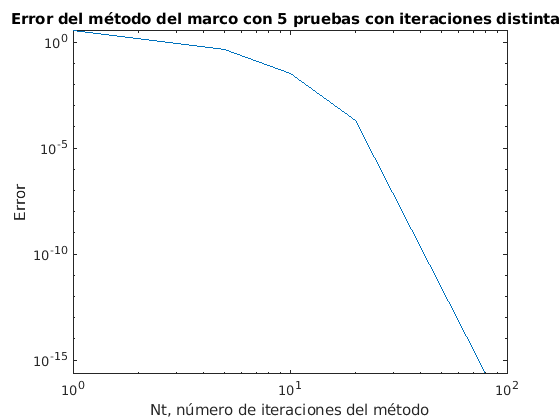


%%%% REPRESENTACIÓN DE GRÁFICAS
%%
%

loglog(Nt,lista_error_MN);
tit = sprintf("Error del método del marco con %d pruebas con iteraciones distintas", num_aprox);
title(tit)
xlabel("Nt, número de iteraciones del método")
ylabel("Error")

#### Al cambiar los bounds (por ejemplo de 1 a 3), la primera iteración es 1/3 menor de lo que valía con 1.

## OJO! El método funciona aunque le demos bounds que no son los óptimos, incluso si nos pasamos de la cota. Luego NO hace falta calcular los AUTOVALORES DE S para sacar los bounds!! vale cualesquiera. INVESTIGAR!!!!!

Mi hipótesis es que los bounds sólo afectan a la velocidad de convergencia, no a la convergencia en si.

Para ver la **VELOCIDAD DE CONVERGENCIA**, miramos la pendiente de la recta del error!!

pendiente_error = [];
pendiente_error = [pendiente_error, (log(lista_error_MN(2))-log(lista_error_MN(1))) / (log(Nt(2))-log(Nt(1)))];
pendiente_error = [pendiente_error, (log(lista_error_MN(3))-log(lista_error_MN(2))) / (log(Nt(3))-log(Nt(2)))];
pendiente_error = [pendiente_error, (log(lista_error_MN(4))-log(lista_error_MN(3))) / (log(Nt(4))-log(Nt(3)))];
pendiente_error

$$pendiente\_error = \left(\begin{array}{ccc} -1.2695752220560587832720475442149 & -3.6848279708310257236819051858608 & -7.3696559416614485442326771086362 \end{array}\right)$$